# Project with UQLab

## 1. Initiate UQLab

uqlab;

Copyright 2013-2022, Stefano Marelli and Bruno Sudret, all rights reserved.
This is UQLab, version 2.0
UQLab is distributed under the BSD 3-clause open source license available at: 
C:\Users\upar\Desktop\ArijitFiles\PhD\PhDCourses\UQ\UQLab_Rel2.0.0\LICENSE.

To request special permissions, please contact:
  - Stefano Marelli (<a href="mailto:marelli@ibk.baug.ethz.ch">marelli@ibk.baug.ethz.ch</a>).

Useful commands to get started with UQLab:
uqlab -doc           - Access the available documentation
uqlab -help          - Additional help on how to get started with UQLab
uq_citation help   - Information on how to cite UQLab in publications
uqlab -license       - Display UQLab license information



clear;
mkdir('UQLab_plots');   %Create directory to save plots from UQLab script. Please make sure to delete before re-running the script.

## 2. Defining the model: Capacitance measurement setup with example values

ModelOptions.mFile = 'model_evaluation_1'; % use the provided model_evaluation_1.m file
myModel = uq_createModel(ModelOptions);     % Create the model object

Then the evaluation of model is as follows:

x0 = [100, 30, 1000]; %Input parameters (E, Vr, R)
y0 = uq_evalModel(myModel, x0) %Calculate capacitance in microFarads

y0 = 1.0010

## 3. Defining the probabilistic input model

The inputs for the function are three independent, Gaussian random variables:

% Voltage across the voltage source in V
InputOptions.Marginals(1).Name = 'E';
InputOptions.Marginals(1).Type = 'Gaussian';
InputOptions.Marginals(1).Moments = [100 0.45];

% Voltage across the shunt resistor in V
InputOptions.Marginals(2).Name = 'Vr';
InputOptions.Marginals(2).Type = 'Gaussian';
InputOptions.Marginals(2).Moments = [30 0.12];

% Shunt resistance in ohm
InputOptions.Marginals(3).Name = 'R';
InputOptions.Marginals(3).Type = 'Gaussian';
InputOptions.Marginals(3).Moments = [1000 1.5];

myInput = uq_createInput(InputOptions);    % Create the input object

## **(Extra: Visualising the sample space to visually understand the input distributions) **

## **3.1 Choosing a sampling strategy for the input variables according to their distributions and drawing samples:**

To draw samples from input object, we use the **MC method (throughout the project)**:

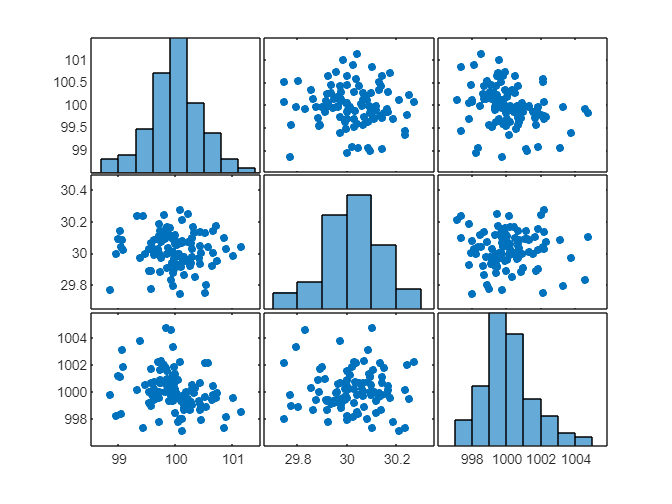

Xtrial = uq_getSample(myInput, 100, 'MC');
plotmatrix(Xtrial)

## 3.2. Performing Monte Carlo simulation on the experimental design

% Xtrial was defined in the section 3.1
Ytrial = uq_evalModel(myModel, Xtrial);

## 3.3 Plot histogram of Monte Carlo runs

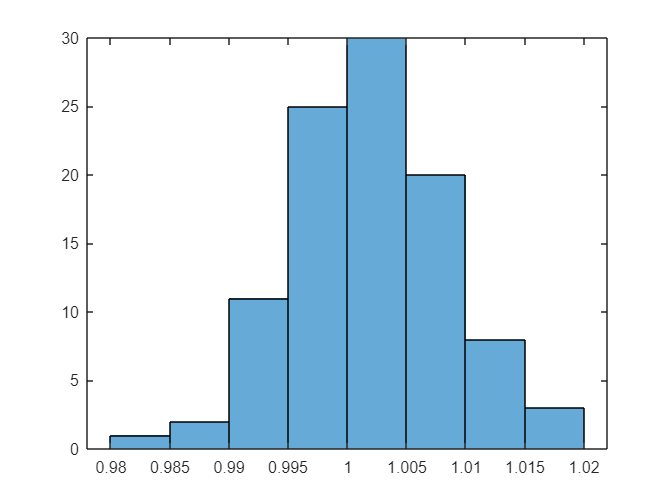

figure
histogram(Ytrial)

## 4. (Small Trial) Creating a first PCE of degree 3 with 60 samples

Note: We use only 60 samples in our experimental design (training set) as this is already enough for our model

## 4.1 Create a regression-based PCE using OLS for coefficient computation

clear metaopts
metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';
metaopts.Method = 'OLS';

metaopts.FullModel = myModel;
metaopts.Input = myInput;

metaopts.Degree = 3;

metaopts.ExpDesign.NSamples = 60; % N needs to be larger than P for OLS to work

myOLSPCE = uq_createModel(metaopts);

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: 8.907470e-12
---                 Calculation finished!                               ---


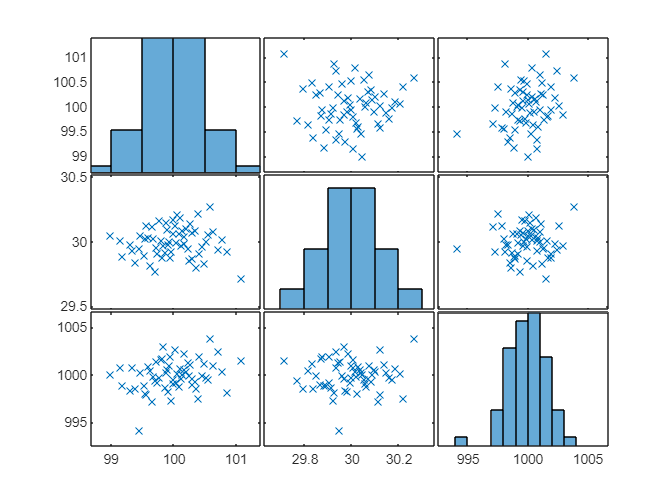

figure
plotmatrix(myOLSPCE.ExpDesign.X, 'x')

### Displaying the magnitude of PCE coefficients:

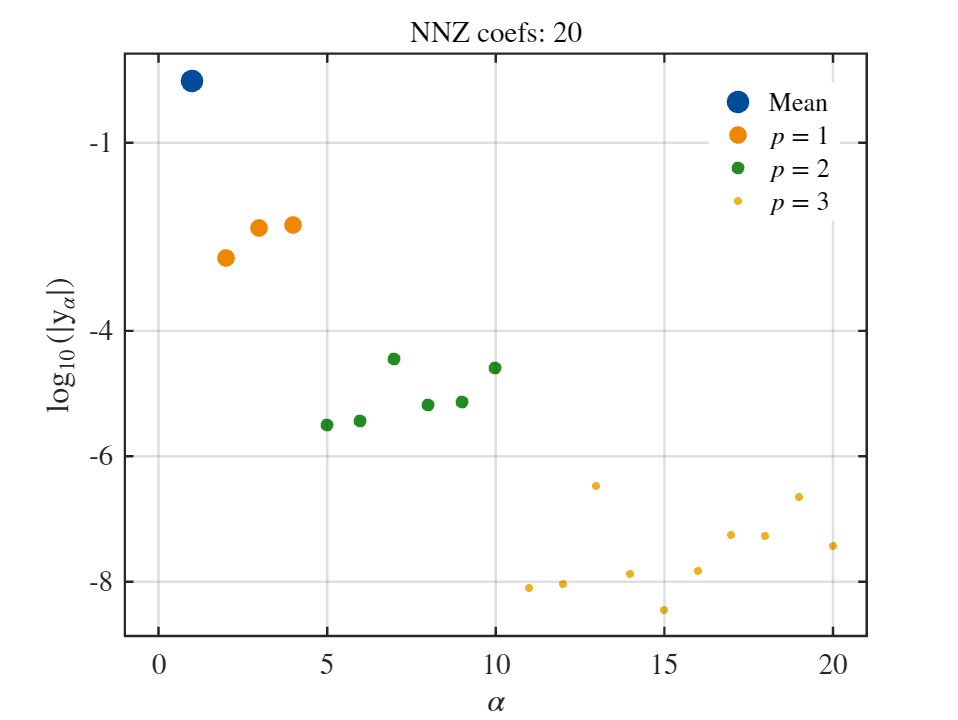

% There are 20 nonzero (nnz) coefficients but also not all of them are
% important as we can see from the figure. Scale on Y axis is logarithmic.
% Mean of the PCE model is given by the coefficient of the constant term.
uq_display(myOLSPCE)

## 4.2 Validation of the trial PCE

Nval_trial = 1e4; % Definining a trial validation set here to 10^4 size
Xval_trial = uq_getSample(myInput, Nval_trial, 'MC');
Yval_trial = uq_evalModel(myModel, Xval_trial); % actual model evaluations for trial validation set

We evaluate the PCE on this validation set:

Yval_trial_PCE = uq_evalModel(myOLSPCE, Xval_trial); % OLS PCE evaluations for trial validation set

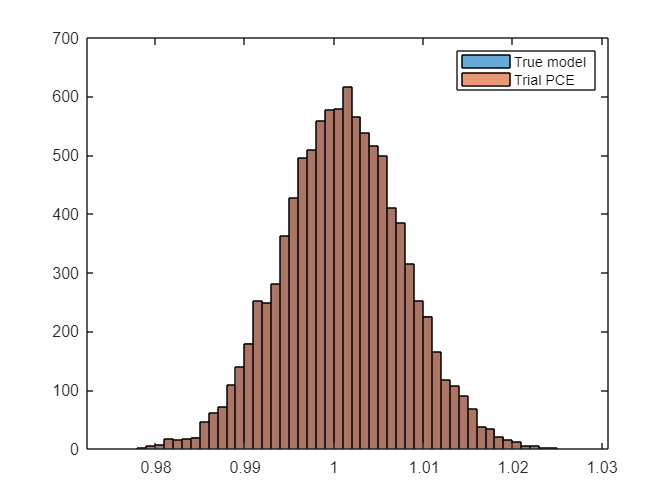

figure
histogram(Yval_trial, 'DisplayName','True model')
hold on
histogram(Yval_trial_PCE, 'DisplayName','Trial PCE')
hold off
legend

The PCE surrogate for the trial case is very accurate as the histograms are overlapping

**Y-Y plot**:

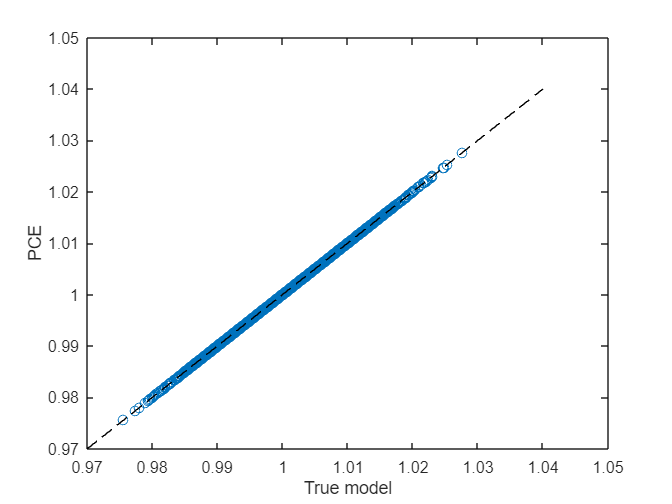

figure
plot(Yval_trial, Yval_trial_PCE, 'o')
hold on
plot([0.97, 1.04], [0.97, 1.04], 'k--')
xlabel('True model')
ylabel('PCE')

The points on Y-Y plot lie exactly on the dashed diagonal line and hence the PCE surrogate is accurate.

## 4.3 Error calculations

The **empirical error** is the error computed on the *experimental design (training set)*:

X = myOLSPCE.ExpDesign.X;
Y = myOLSPCE.ExpDesign.Y;
YPCE = uq_evalModel(myOLSPCE, X);

normalized_empirical_error = sum((Y - YPCE).^2) / sum((Y - mean(Y)).^2) 

normalized_empirical_error = 7.3017e-14

The normalized empirical error of *experimental design* computed by UQLab should be same as the empirical error manually calculated above:

myOLSPCE.Error.normEmpErr

ans = 7.3017e-14

But the empirical error is quite optimistic as it is calculated based on the experimental design (training set) which itself was used to train the OLS based PCE model. Therefore, validation error should be a better error estimate.

The **validation error** is the error computed on the *validation set*:

Yval_OLSPCE = uq_evalModel(myOLSPCE, Xval_trial);

normalized_validation_error = mean((Yval_trial - Yval_OLSPCE).^2) / var(Yval_trial)

normalized_validation_error = 1.2594e-12

With this, we conclude that the empirical error is smaller than the validation error as expected due to overfitting.

Alternatively, the Leave-One-Out *LOO error* calculated by UQLab is:

myOLSPCE.Error.LOO

ans = 2.5370e-12

LOO error is very close to the validation error calculated above and hence it can be a good estimate/replacement for the validation error.

## 4.4 Convergence study

Defining a validation set of size 10^6, also to be used for further analysis from here onwards.

Nval = 1e6; % Definining a full validation set here to 10^6 size
Xval = uq_getSample(myInput, Nval, 'MC');
Yval = uq_evalModel(myModel, Xval); % actual model evaluations for the full validation set

### **4.4.1 Convergence as a function of polynomial degree:**

% Convergence study: fixed N = 60 with MC sampling, increasing degree from 0 to 5
clear metaopts

N = 60;
max_degree = 6;
degree_range = 0:max_degree;

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';
metaopts.Method = 'OLS';
metaopts.Input = myInput;
metaopts.FullModel = myModel;
metaopts.ExpDesign.NSamples = N;
metaopts.Input.Sampling = 'MC';

clear mu
clear vari

for degree = degree_range
    metaopts.Degree = degree;
    myOLSPCE(degree+1) = uq_createModel(metaopts);
    mu(degree+1) = myOLSPCE(degree+1).PCE.Moments.Mean;
    vari(degree+1) = myOLSPCE(degree+1).PCE.Moments.Var;
end

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 0 and qNorm 1.00 for output variable 1
Final LOO error estimate: 1.069243e+00
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 1 and qNorm 1.00 for output variable 1
Final LOO error estimate: 5.028698e-05
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 2 and qNorm 1.00 for output variable 1
Final LOO error estimate: 2.454070e-08
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Fin

### Visualization

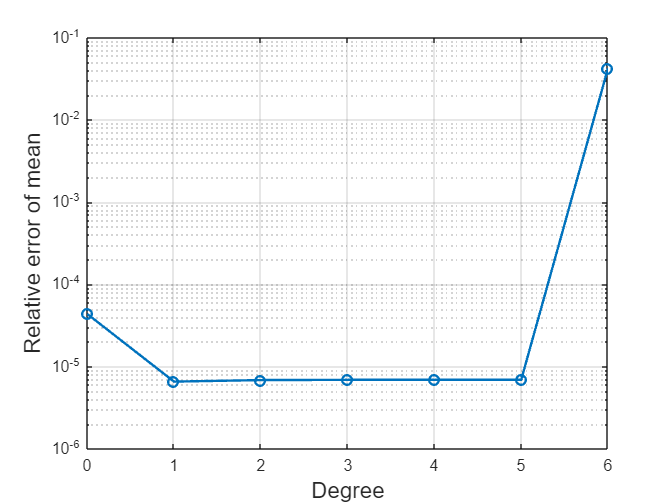

mean_val_set =  mean(Yval);   % Sample mean of a large validation set
rel_mean_error_OLSPCE = abs(mu - mean_val_set)/abs(mean_val_set);

figure
semilogy(degree_range, rel_mean_error_OLSPCE,'-o','LineWidth',1.5)
grid on
xlabel('Degree','FontSize',14)
ylabel('Relative error of mean','FontSize',14)
exportgraphics(gcf, 'UQLab_plots/Mean_OLS_FixN_VaryDeg.png','Resolution',600)

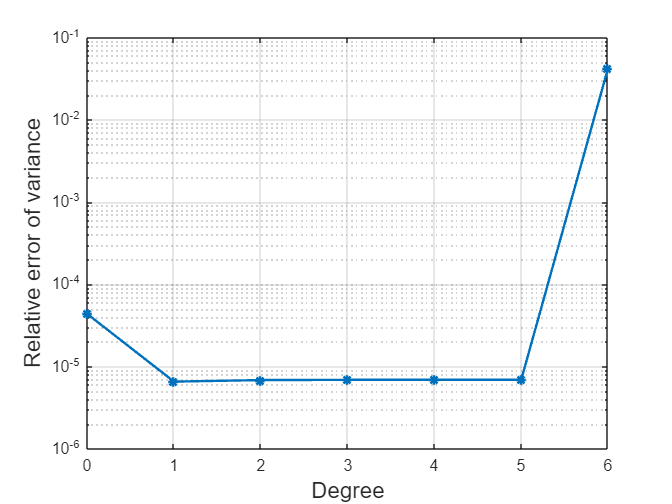

variance_val_set = var(Yval);   % Sample variance of a large validation set
rel_var_error_OLSPCE = abs(vari - variance_val_set)/abs(variance_val_set);

figure
semilogy(degree_range, rel_mean_error_OLSPCE,'-*','LineWidth',1.5)
grid on
xlabel('Degree','FontSize',14)
ylabel('Relative error of variance','FontSize',14)
exportgraphics(gcf, 'UQLab_plots/Var_OLS_FixN_VaryDeg.png','Resolution',600)

### **4.4.2 Convergence as a function of number of samples in experimental design:**

% Convergence study: degree = 3 or 4, increasing N from 10 to 60 for 25 values in total 

%Re-initializing the UQ input object

% Voltage across the voltage source in V
InputOptions.Marginals(1).Name = 'E';
InputOptions.Marginals(1).Type = 'Gaussian';
InputOptions.Marginals(1).Moments = [100 0.45];

% Voltage across the shunt resistor in V
InputOptions.Marginals(2).Name = 'Vr';
InputOptions.Marginals(2).Type = 'Gaussian';
InputOptions.Marginals(2).Moments = [30 0.12];

% Shunt resistance in ohm
InputOptions.Marginals(3).Name = 'R';
InputOptions.Marginals(3).Type = 'Gaussian';
InputOptions.Marginals(3).Moments = [1000 1.5];

myInput = uq_createInput(InputOptions);    % Create the input object


p = [3 4];
N_sizes = linspace(10,60,25);

% Fixing the experimental design/sample set for comparing PCE degree 3 and 4
X_fix = cell(size(N_sizes));
Y_fix = cell(size(N_sizes));

for N_size = 1:numel(N_sizes)
    X_fix{N_size} = uq_getSample(myInput, floor(N_sizes(N_size)), 'MC'); % Monte Carlo based sampling
    Y_fix{N_size} = uq_evalModel(myModel, X_fix{N_size});
end

clear metaopts

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';
metaopts.Method = 'OLS';
metaopts.Input = myInput;
metaopts.FullModel = myModel;
metaopts.Input.Sampling = 'MC';

metaopts.Degree = p(1);

clear mu
clear vari

for N_size = 1:numel(N_sizes)
    % metaopts.ExpDesign.NSamples = floor(N_sizes(N_size));
    metaopts.ExpDesign.X = X_fix{N_size};  %Fixing the experimental design to the drawn samples
    metaopts.ExpDesign.Y = Y_fix{N_size};

    metaopts.Degree = p(1);
    myOLSPCE(N_size) = uq_createModel(metaopts);
    mu(N_size) = myOLSPCE(N_size).PCE.Moments.Mean;
    vari(N_size) = myOLSPCE(N_size).PCE.Moments.Var;
end

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf


clear metaopts

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';
metaopts.Method = 'OLS';
metaopts.Input = myInput;
metaopts.FullModel = myModel;
metaopts.Input.Sampling = 'MC';

metaopts.Degree = p(2);

clear mu_1
clear vari_1

for N_size = 1:numel(N_sizes)
    % metaopts.ExpDesign.NSamples = floor(N_sizes(N_size));
    metaopts.ExpDesign.X = X_fix{N_size};  %Fixing the experimental design to the drawn samples
    metaopts.ExpDesign.Y = Y_fix{N_size};
    
    myOLSPCE_1(N_size) = uq_createModel(metaopts);
    mu_1(N_size) = myOLSPCE_1(N_size).PCE.Moments.Mean;
    vari_1(N_size) = myOLSPCE_1(N_size).PCE.Moments.Var;
end

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 4 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 4 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 4 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 4 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf


### Visualization

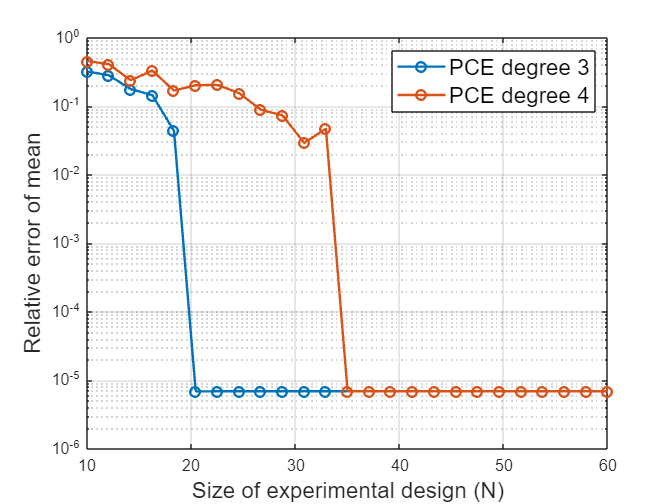

mean_val_set =  mean(Yval);
rel_mean_error_OLSPCE = abs(mu - mean_val_set)/abs(mean_val_set);
rel_mean_error_OLSPCE_1 = abs(mu_1 - mean_val_set)/abs(mean_val_set);

figure
semilogy(N_sizes, rel_mean_error_OLSPCE,'-o','LineWidth',1.5)
hold on
semilogy(N_sizes, rel_mean_error_OLSPCE_1,'-o','LineWidth',1.5)
grid on
xlabel('Size of experimental design (N)','FontSize',14)
ylabel('Relative error of mean','FontSize',14)
legend(['PCE degree ' int2str(p(1))], ['PCE degree ' int2str(p(2))],'FontSize',14)
exportgraphics(gcf, 'UQLab_plots/Mean_OLS_FixDeg_VaryN.png','Resolution',600)

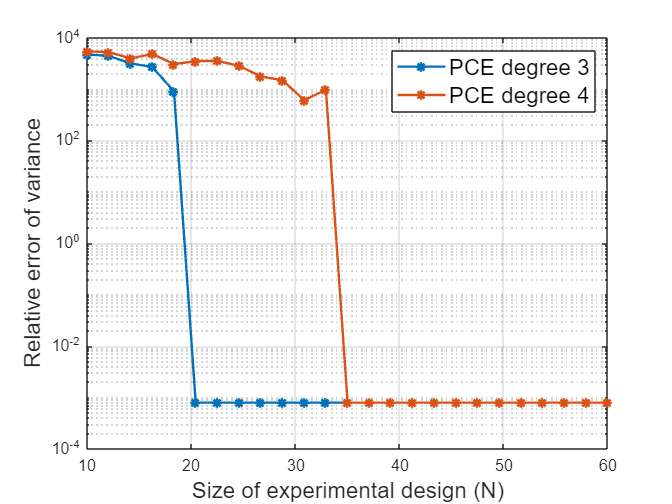

variance_val_set = var(Yval);
rel_var_error_OLSPCE = abs(vari - variance_val_set)/abs(variance_val_set);
rel_var_error_OLSPCE_1 = abs(vari_1 - variance_val_set)/abs(variance_val_set);

figure
semilogy(N_sizes, rel_var_error_OLSPCE,'-*','LineWidth',1.5)
hold on
semilogy(N_sizes, rel_var_error_OLSPCE_1,'-*','LineWidth',1.5)
grid on
xlabel('Size of experimental design (N)','FontSize',14)
ylabel('Relative error of variance','FontSize',14)
legend(['PCE degree ' int2str(p(1))], ['PCE degree ' int2str(p(2))],'FontSize',14)
exportgraphics(gcf, 'UQLab_plots/Var_OLS_FixDeg_VaryN.png','Resolution',600)

## 4.5 Truncation analysis on number of basis elements (Showing the effect of Q-Norm)

clear metaopts
metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';
metaopts.Method = 'OLS';

metaopts.FullModel = myModel;
metaopts.Input = myInput;

metaopts.Degree = 4;
% >>>
metaopts.TruncOptions.qNorm = 0.8; % between 0 and 1
metaopts.TruncOptions.MaxInteraction = 3; % between 1 and 3 as we have 3 dimensions
% <<<
metaopts.ExpDesign.NSamples = 200; % N needs to be larger than P for OLS to work

myOLSPCE = uq_createModel(metaopts);

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 4 and qNorm 0.80 for output variable 1
Final LOO error estimate: 8.645284e-13
---                 Calculation finished!                               ---


Number of basis elements (number of coefficients in the PCE):

numBasisElements = numel(myOLSPCE.PCE.Coefficients)

numBasisElements = 23

## 4.6 Convergence study of full vs sparse PCE (LARS)

The degree and the hyperbolic truncation for LARS-PCE are determined adaptively (based on the LOO error), degree of OLS-PCE is fixed as 3. The samples drawn for both LARS-PCE and OLS-PCE are same for comparing the results.

% OLS-PCE: fixed degree = 3, increasing N from 10 to 60 for 25 values in total
clear metaopts

p = 3;

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';
metaopts.Method = 'OLS';
metaopts.Input = myInput;
metaopts.FullModel = myModel;
metaopts.Degree = p(1);

clear mu_OLS
clear vari_OLS

for N_size = 1:numel(N_sizes)
    metaopts.ExpDesign.X = X_fix{N_size};  %Fixing the experimental design to the previously drawn samples in section 4.4.2
    metaopts.ExpDesign.Y = Y_fix{N_size};
    
    myOLSPCE(N_size) = uq_createModel(metaopts); %Create the OLS-PCE
    mu_OLS(N_size) = myOLSPCE(N_size).PCE.Moments.Mean;
    vari_OLS(N_size) = myOLSPCE(N_size).PCE.Moments.Var;
end

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf


% LARS-PCE: adaptive degree and truncation, increasing N from 10 to 60 for 25 values in total
clear metaopts

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';
metaopts.Method = 'LARS'; % LARS solver for sparse regression
metaopts.Input = myInput;
metaopts.FullModel = myModel;

% Degree- and q-norm adaptivity:
metaopts.Degree = 1:10;
metaopts.TruncOptions.qNorm = 0.5:0.1:1.0;

clear mu_LARS
clear vari_LARS

for N_size = 1:numel(N_sizes)
    metaopts.ExpDesign.X = X_fix{N_size};  %Fixing the experimental design to the previously drawn samples in section 4.4.2
    metaopts.ExpDesign.Y = Y_fix{N_size};
    
    myLARSPCE(N_size) = uq_createModel(metaopts); %Create the LARS-PCE
    mu_LARS(N_size) = myLARSPCE(N_size).PCE.Moments.Mean;
    vari_LARS(N_size) = myLARSPCE(N_size).PCE.Moments.Var;
end

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 1 and qNorm 0.50 for output variable 1
Final LOO error estimate: 5.713207e-05
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 4 and qNorm 0.50 for output variable 1
Final LOO error estimate: 2.662484e-05
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 2 and qNorm 1.00 for output variable 1
Final LOO error estimate: 2.618600e-06
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 2 and qNorm 1.00 for output variab

rel_mean_error_OLSPCE = abs(mu_OLS - mean_val_set)/abs(mean_val_set);
rel_var_error_OLSPCE = abs(vari_OLS - variance_val_set)/abs(variance_val_set);

rel_mean_error_LARSPCE = abs(mu_LARS - mean_val_set)/abs(mean_val_set);
rel_var_error_LARSPCE = abs(vari_LARS - variance_val_set)/abs(variance_val_set);

### Visualization

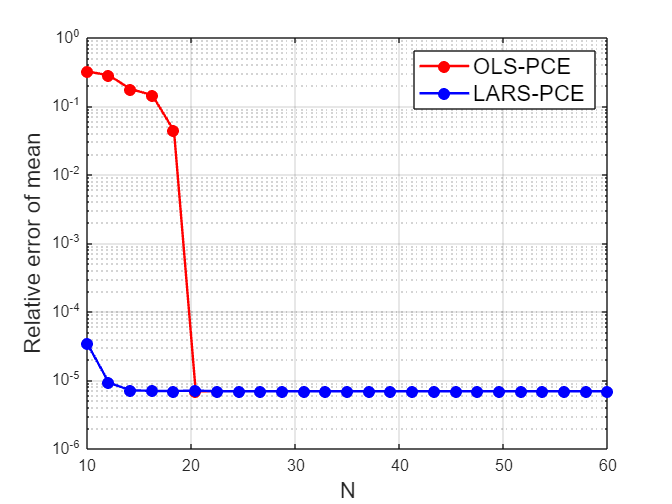

figure
semilogy(N_sizes, rel_mean_error_OLSPCE, '-o', 'Color', 'red', 'MarkerFaceColor', 'red','LineWidth',1.5)
hold on
semilogy(N_sizes, rel_mean_error_LARSPCE, '-o', 'Color', 'blue', 'MarkerFaceColor', 'blue','LineWidth',1.5)
grid on
xlabel('N','FontSize',14)
ylabel('Relative error of mean','FontSize',14)
legend('OLS-PCE', 'LARS-PCE','FontSize',14)
exportgraphics(gcf, 'UQLab_plots/Mean_LARSvsOLS.png','Resolution',600)

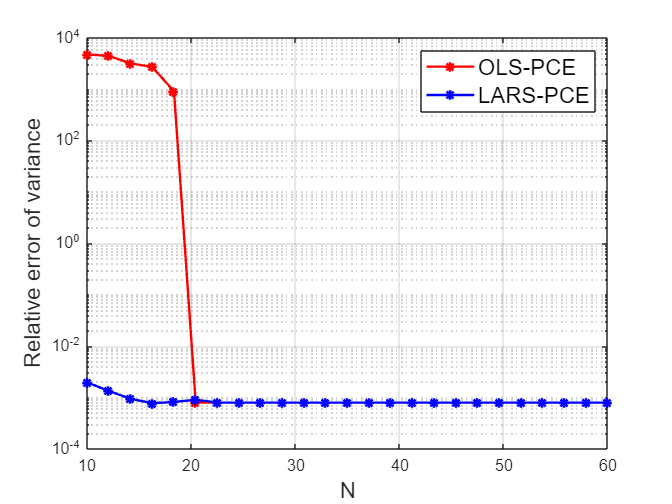

figure
semilogy(N_sizes, rel_var_error_OLSPCE, '-*', 'Color', 'red', 'MarkerFaceColor', 'red','LineWidth',1.5)
hold on
semilogy(N_sizes, rel_var_error_LARSPCE, '-*', 'Color', 'blue', 'MarkerFaceColor', 'blue','LineWidth',1.5)
grid on
xlabel('N','FontSize',14)
ylabel('Relative error of variance','FontSize',14)
legend('OLS-PCE', 'LARS-PCE','FontSize',14)
exportgraphics(gcf, 'UQLab_plots/Var_LARSvsOLS.png','Resolution',600)

## 4.7 Convergence study of full vs sparse PCE (OMP)

The degree and the hyperbolic truncation for OMP-PCE are determined adaptively (based on the LOO error), degree of OLS-PCE is fixed as 3. The samples drawn for both OMP-PCE and OLS-PCE are same for comparing the results.

% OLS-PCE: fixed degree = 3, increasing N from 10 to 60 for 25 values in total
clear metaopts

p = 3;

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';
metaopts.Method = 'OLS';
metaopts.Input = myInput;
metaopts.FullModel = myModel;
metaopts.Degree = p(1);

clear mu_OLS
clear vari_OLS

for N_size = 1:numel(N_sizes)
    metaopts.ExpDesign.X = X_fix{N_size};  %Fixing the experimental design to the previously drawn samples in section 4.4.2
    metaopts.ExpDesign.Y = Y_fix{N_size};
    
    myOLSPCE(N_size) = uq_createModel(metaopts); %Create the OLS-PCE
    mu_OLS(N_size) = myOLSPCE(N_size).PCE.Moments.Mean;
    vari_OLS(N_size) = myOLSPCE(N_size).PCE.Moments.Var;
end

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients stopped at polynomial degree 3 and qNorm 1.00 for output variable 1
Final LOO error estimate: Inf


% OMP-PCE: adaptive degree and truncation, increasing N from 10 to 60 for 25 values in total
clear metaopts

metaopts.Type = 'Metamodel';
metaopts.MetaType = 'PCE';
metaopts.Method = 'OMP'; % OMP solver for sparse regression
metaopts.Input = myInput;
metaopts.FullModel = myModel;

% Degree- and q-norm adaptivity:
metaopts.Degree = 1:10;
metaopts.TruncOptions.qNorm = 0.5:0.1:1.0;

clear mu_OMP
clear vari_OMP

for N_size = 1:numel(N_sizes)
    metaopts.ExpDesign.X = X_fix{N_size};  %Fixing the experimental design to the previously drawn samples in section 4.4.2
    metaopts.ExpDesign.Y = Y_fix{N_size};
    
    myOMPPCE(N_size) = uq_createModel(metaopts); %Create the OMP-PCE
    mu_OMP(N_size) = myOMPPCE(N_size).PCE.Moments.Mean;
    vari_OMP(N_size) = myOMPPCE(N_size).PCE.Moments.Var;
end

---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 1 and qNorm 0.50 for output variable 1
Final LOO error estimate: 5.713207e-05
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 2 and qNorm 1.00 for output variable 1
Final LOO error estimate: 5.242837e-05
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 2 and qNorm 1.00 for output variable 1
Final LOO error estimate: 2.372508e-07
---                 Calculation finished!                               ---
---   Calculating the PCE coefficients by regression.   ---
The estimation of PCE coefficients converged at polynomial degree 3 and qNorm 1.00 for output variab

rel_mean_error_OLSPCE = abs(mu_OLS - mean_val_set)/abs(mean_val_set);
rel_var_error_OLSPCE = abs(vari_OLS - variance_val_set)/abs(variance_val_set);

rel_mean_error_OMPPCE = abs(mu_OMP - mean_val_set)/abs(mean_val_set);
rel_var_error_OMPPCE = abs(vari_OMP - variance_val_set)/abs(variance_val_set);

### Visualization

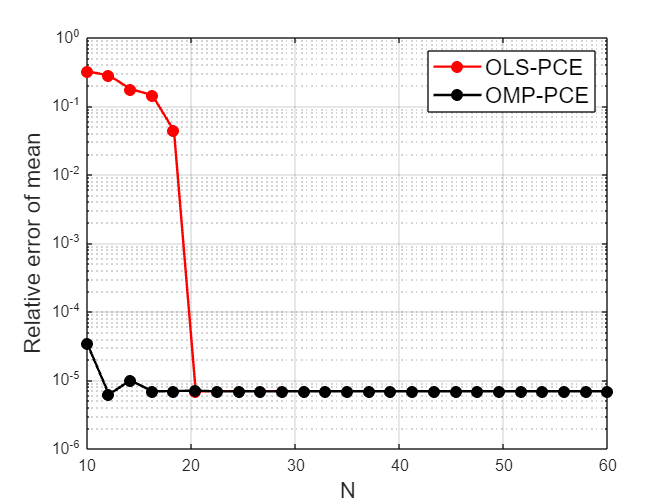

figure
semilogy(N_sizes, rel_mean_error_OLSPCE, '-o', 'Color', 'red', 'MarkerFaceColor', 'red','LineWidth',1.5)
hold on
semilogy(N_sizes, rel_mean_error_OMPPCE, '-o', 'Color', 'black', 'MarkerFaceColor', 'black','LineWidth',1.5)
grid on
xlabel('N','FontSize',14)
ylabel('Relative error of mean','FontSize',14)
legend('OLS-PCE', 'OMP-PCE','FontSize',14)
exportgraphics(gcf, 'UQLab_plots/Mean_OMPvsOLS.png','Resolution',600)

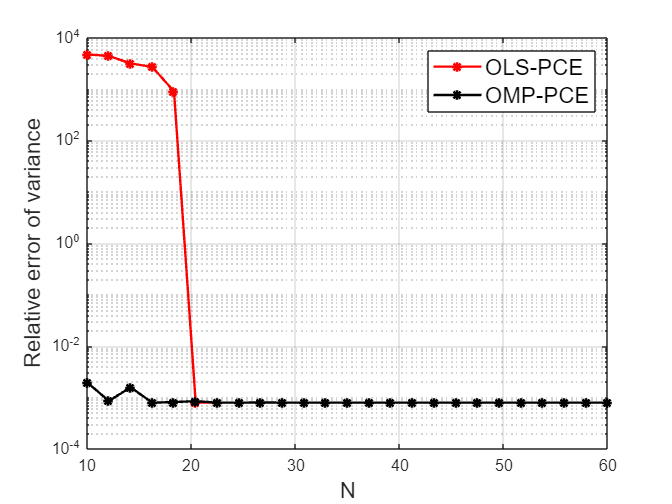

figure
semilogy(N_sizes, rel_var_error_OLSPCE, '-*', 'Color', 'red', 'MarkerFaceColor', 'red','LineWidth',1.5)
hold on
semilogy(N_sizes, rel_var_error_OMPPCE, '-*', 'Color', 'black', 'MarkerFaceColor', 'black','LineWidth',1.5)
grid on
xlabel('N','FontSize',14)
ylabel('Relative error of variance','FontSize',14)
legend('OLS-PCE', 'OMP-PCE','FontSize',14)
exportgraphics(gcf, 'UQLab_plots/Var_OMPvsOLS.png','Resolution',600)